clear all
close all

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

NOTES = 84;

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6) / 2;
Tab_F = k' .* repmat(Tab_F_1, 7, 1);

M = zeros(7, 12);
Ms = M;

Изменяемые параметры

NFFT = 1024;
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
ds = 2;                 % В сколько раз уменьшить спектр. Минимум 2 - нормально

Получаю отдельные колонки для отдельных нот

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей
data = data(:, 1:87);       % Откидываем 5тую октаву ноту До
data = data(:,4:end);       % Откидываю первые 3 ноты суб-контр октавы

Заполняю Х и У с вырезками нот длинной в NFFT

Y = zeros(N*NOTES, 1);
X = zeros([N*NOTES, NFFT+N_zero]);    % С интерполяцией
% X = zeros([N*NOTES, NFFT]);             % Без интерполяции

for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),NFFT,[])';
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% OPTIONAL
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Window function
    % Add Hamming window
    h = hamming(NFFT)';
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end

Разделяю данные на тестовые и тренировочные

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear X z

Нахожу спектры этих данных и урезаю их (беру 1/ds от спектра). А так же нормализирую спектры

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

% Normalization of data
XTest_ds = XTest_ds ./ sum(XTest_ds, 2);
XTrain_ds = XTrain_ds ./ sum(XTrain_ds, 2);

clear XTest XTrain

Нахожу mean and std для матрицы Ms 7x12

mean_M = zeros([NOTES 7 12]);
std_M = zeros([NOTES 7 12]);

Indexes = floor(Tab_F);   % NOT FLAT!!!
v1 = [1 1 1 1 1 1 1 ] * 1/10;
v2 = [0 1 1 1 1 1 1 ] * 1/8;
v3 = [0 0 1 1 1 1 1 ] * 1/6;
v4 = [0 0 0 1 1 1 1 ] * 1/4;
v5 = [0 0 0 0 1 1 1 ] * 1/3; 
v6 = [0 0 0 0 0 1 1 ] * 1/2;
v7 = [0 0 0 0 0 0 1 ];
V = [v1; v2; v3; v4; v5; v6; v7];
clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7

% i = number of note
for i = 1:NOTES
    
    ind = find(YTrain==i); 
    X_note = XTrain_ds(ind, :);
    
    Ncuts = length(ind);
    temp_M = zeros([Ncuts 7 12]);
    
    % k = single cut of NFFT
    for k = 1:Ncuts
        
        x = X_note(k, :);    % Current signal
        
        M = x(Indexes);          % Заполняем матрицу нот
        Ms = V * M;
        
        temp_M(k, :, :) = Ms;

    end
    
    mean_M(i, :, :) = mean(temp_M, 1);
    std_M(i, :, :) = std(temp_M, 1);

end

Проверяю модель

rand_ind = randi(size(XTest_ds, 1));
test_sig = XTest_ds(rand_ind, :);
test_label = YTest(rand_ind);

M = test_sig(Indexes);          % Заполняем матрицу нот
Ms = V * M;

Prob_note = ones([NOTES, 1]);

tic
% i = number of note
for i = 1:NOTES
    
    % k = single sample of Ms
    for k = 1:(7*12)
        
        m = Ms(k);
        std_cur = std_M(i, k);    % Current std
        mean_cur = mean_M(i, k);  % Current mean
         
        p = gaussmf(m, [std_cur mean_cur]);

        Prob_note(i) = Prob_note(i) * p;
    end
    
end
toc

Elapsed time is 0.116648 seconds.


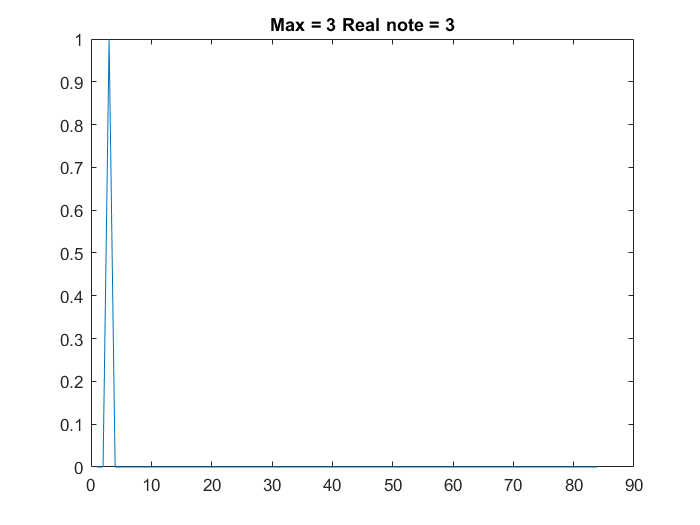


Prob_note = Prob_note / sum(Prob_note);

figure
plot(Prob_note)
title("Max = " + string(find(Prob_note==max(Prob_note))) + " Real note = " + string(test_label))

Точный поиск ошибки классификатора

p_error = 0;
my_notes = zeros([STest 1]);
true_notes = zeros([STest 1]);

tic
for j = 1:STest
    
    test_sig = XTest_ds(j, :);
    test_label = YTest(j);

    M = test_sig(Indexes);          % Заполняем матрицу нот
    Ms = V * M;
    
    Prob_note = ones([NOTES, 1]);
    
    % i = number of note
    for i = 1:NOTES
        
        % k = single sample of Ms
        for k = 1:(7*12)
            
            m = Ms(k);
            std_cur = std_M(i, k);    % Current std
            mean_cur = mean_M(i, k);  % Current mean
             
            p = gaussmf(m, [std_cur mean_cur]);
    
            Prob_note(i) = Prob_note(i) * p;
        end
        
    end
    
    note = find(Prob_note==max(Prob_note));
    
    if note ~= test_label
        p_error = p_error + 1;
    end
    
    my_notes(j) = note(1);% Sometimes it returns 1x88 zeros vector  
    true_notes(j) = test_label;
    
end
toc

Elapsed time is 95.060621 seconds.


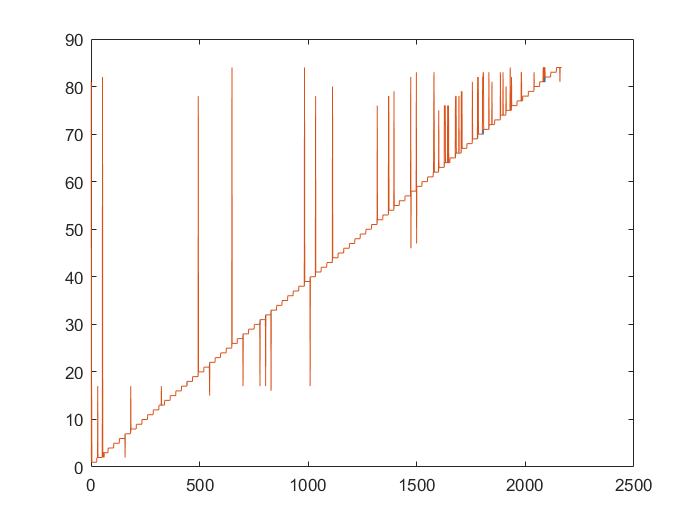


figure
plot(true_notes)
hold on
plot(my_notes)
hold off


p_error = 100 * p_error / STest

p_error = 3.5533